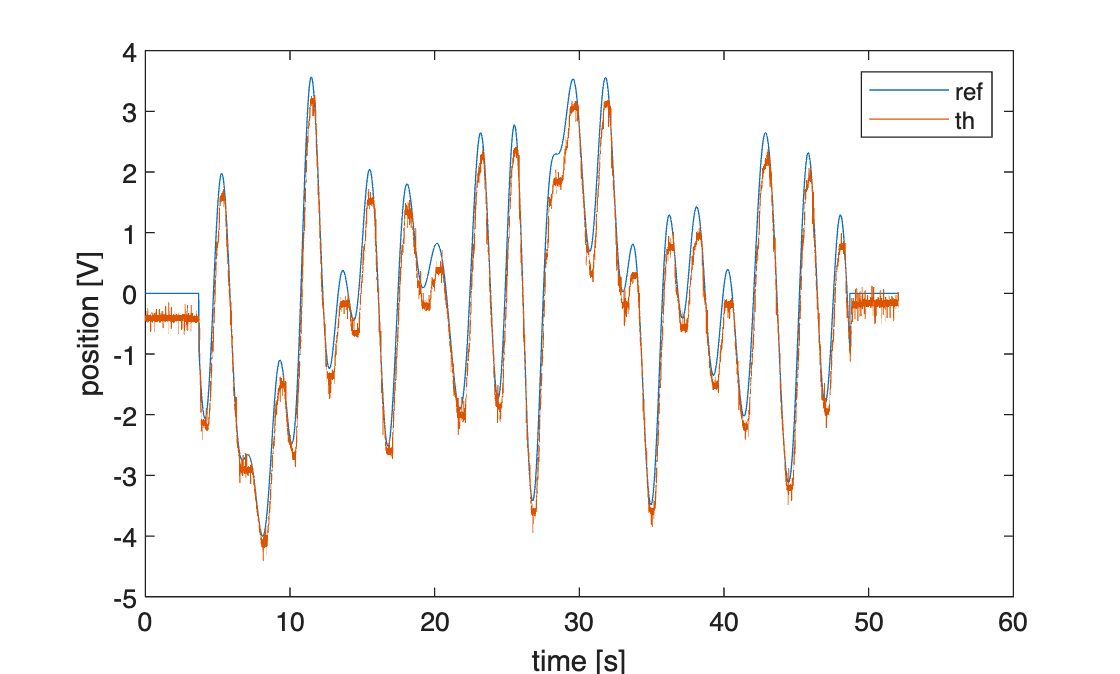

clear
load multisin_beam.mat
load random_steps.mat
load OL_acquisition.mat

th_ref1 = ...
    multisin_beam.Y(1).Data';
u1 = ...
    multisin_beam.Y(2).Data';
th_filtered1 = ...
    multisin_beam.Y(3).Data';
th1 = ...
    multisin_beam.Y(4).Data';
t1  = ...
    multisin_beam.X.Data';

th_ref2 = ...
    random_steps.Y(1).Data';
u2 = ...
    random_steps.Y(2).Data';
th_filtered2 = ...
    random_steps.Y(3).Data';
th2 = ...
    random_steps.Y(4).Data';
t2  = ...
    random_steps.X.Data';

u3 = ...
    OL_acquisition.Y(1).Data';
th3 = ...
    OL_acquisition.Y(2).Data';
t3  = ...
    OL_acquisition.X.Data';

figure
plot(t1,[th_ref1 th1])
ylabel('position [V]')
xlabel('time [s]')
legend('ref','th')

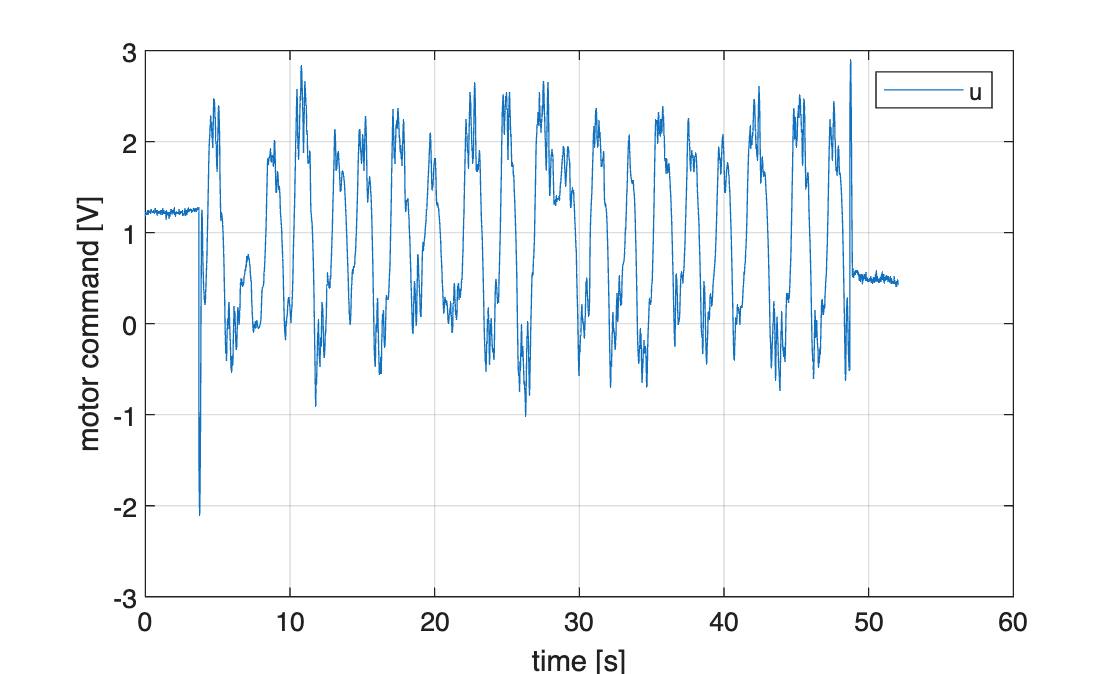

figure
plot(t1,u1)
ylabel('motor command [V]')
xlabel('time [s]')
grid on
legend('u')

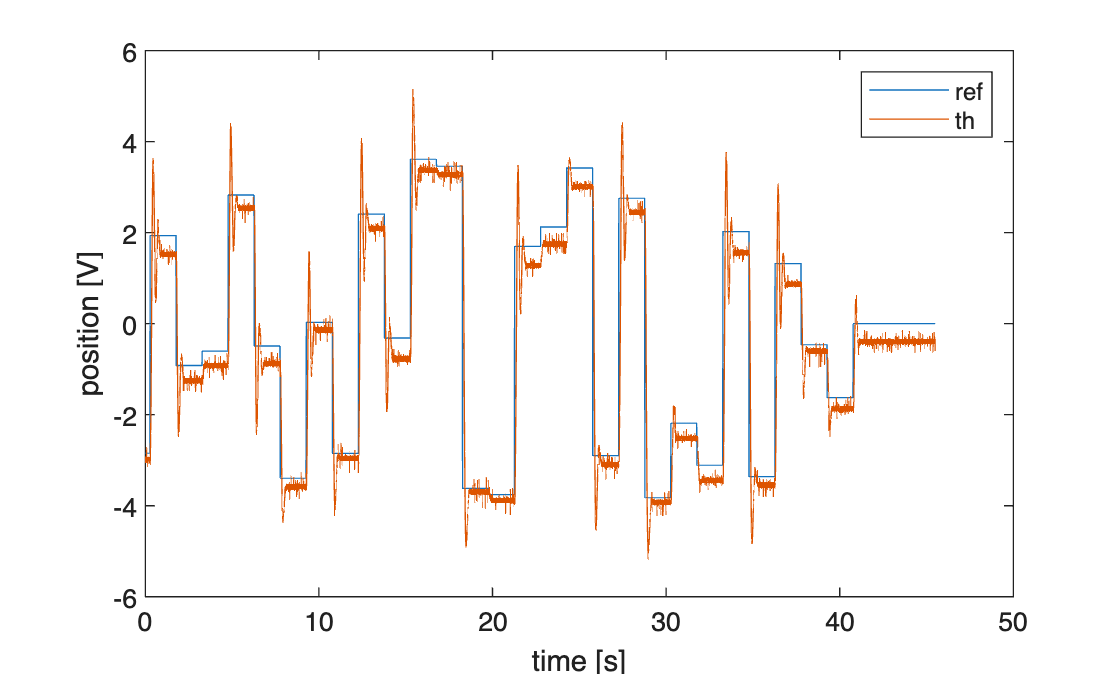

figure
plot(t2,[th_ref2 th2])
ylabel('position [V]')
xlabel('time [s]')
legend('ref','th')

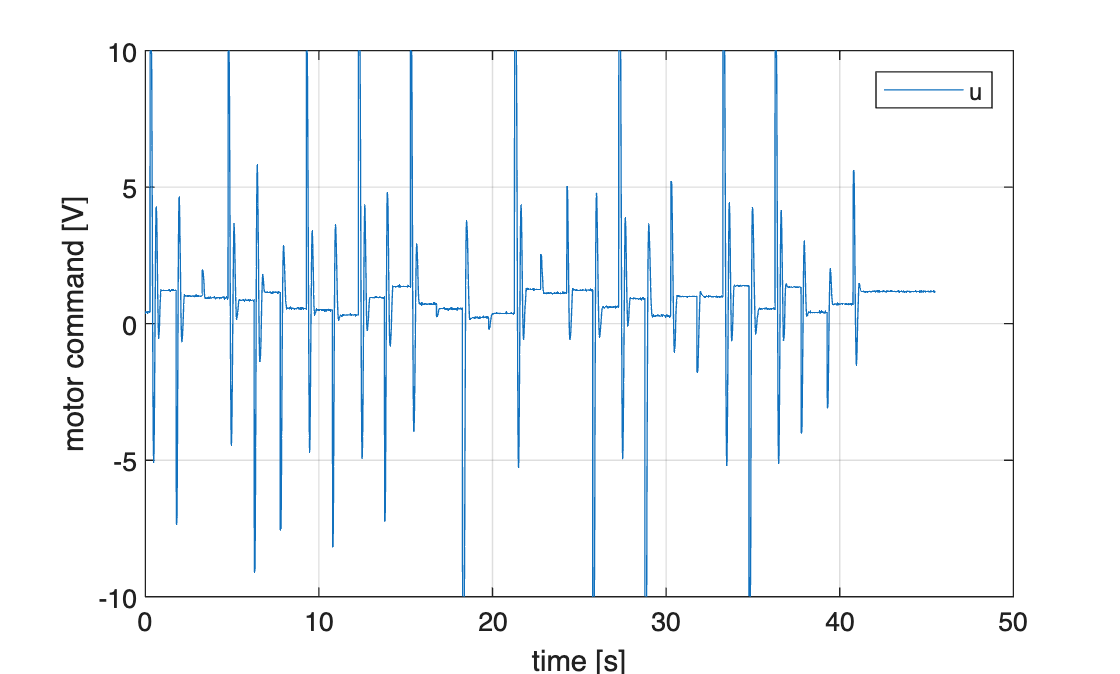

figure
plot(t2,u2)
ylabel('motor command [V]')
xlabel('time [s]')
grid on
legend('u')

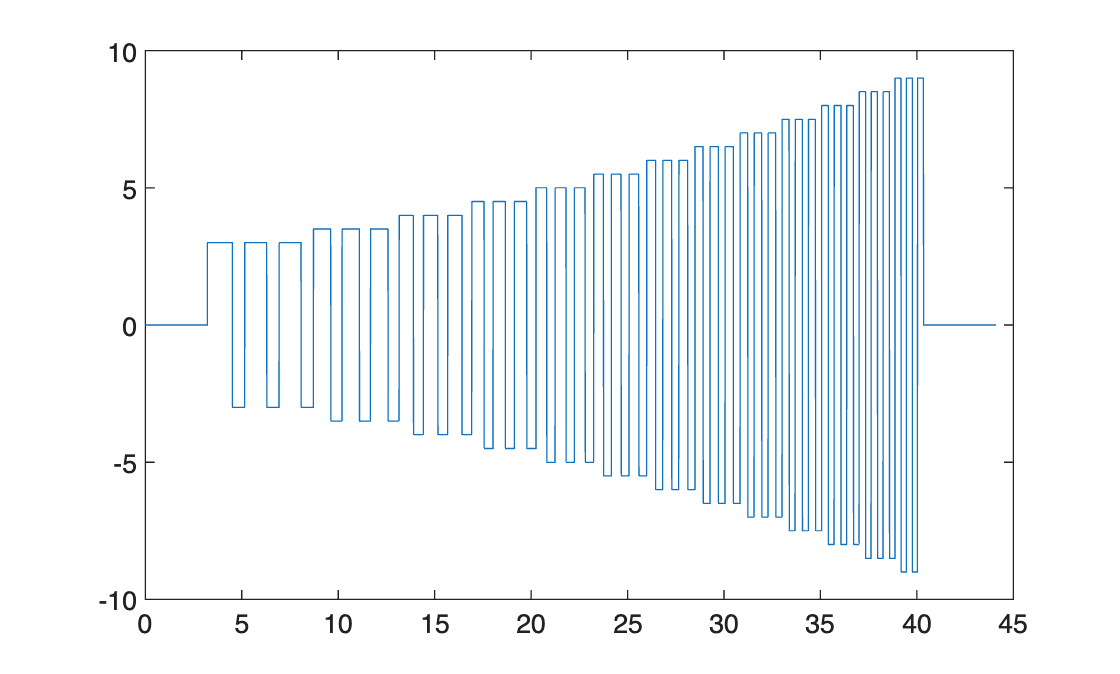

figure
plot(t3,u3)

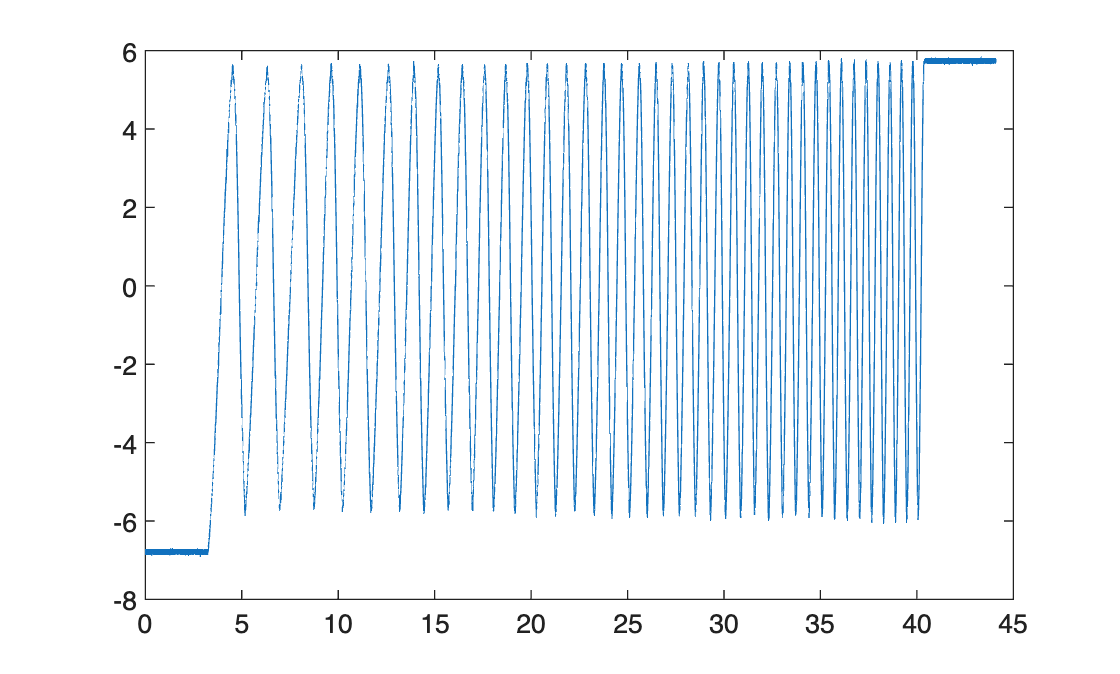

figure
plot(t3,th3)

preprocess for sysid

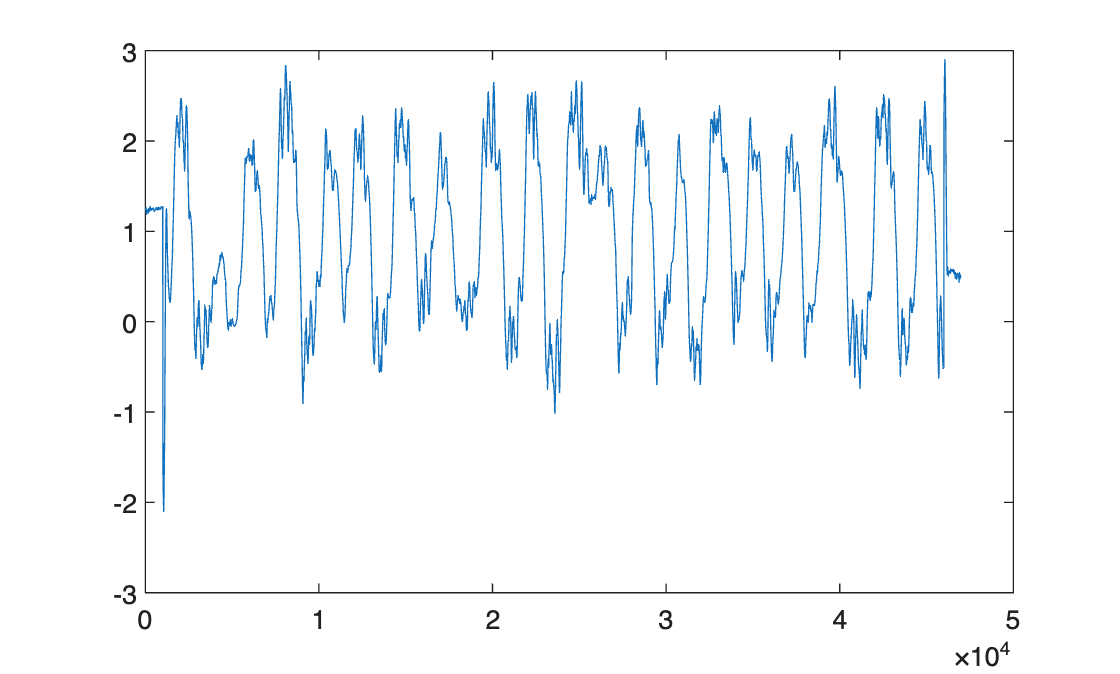

indStart = find(diff(th_ref1),1,'first');
indEnd   = find(diff(th_ref1),1,'last');
samplesMore = 1000;

indSelect = (indStart-samplesMore):indEnd+samplesMore;
% u1 = u1-mean(u1(1:indStart));
u1 = u1(indSelect);
% th1 = th1-mean(th1(1:indStart));
th1=th1(indSelect);

plot(u1)

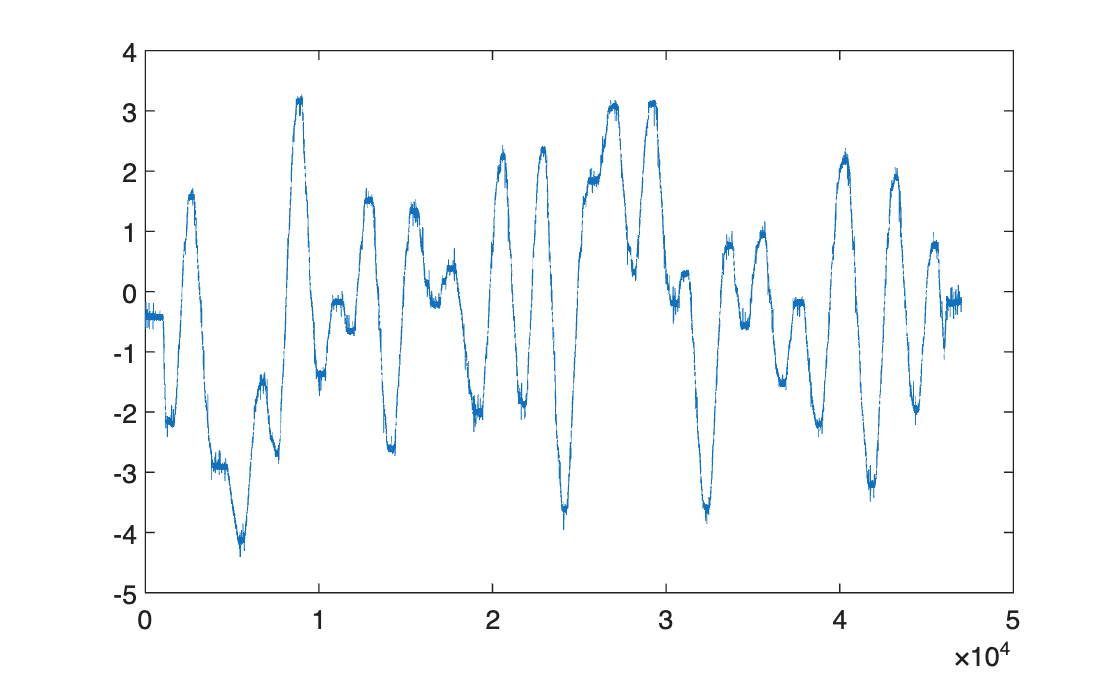

plot(th1)

u = u1;
y = th1;

save multisin_beam_uy.mat u y

u = u2;
y = th2;

save random_steps_uy.mat u y

u = u3;
y = th3;

save increasing_steps_uy.mat u y
